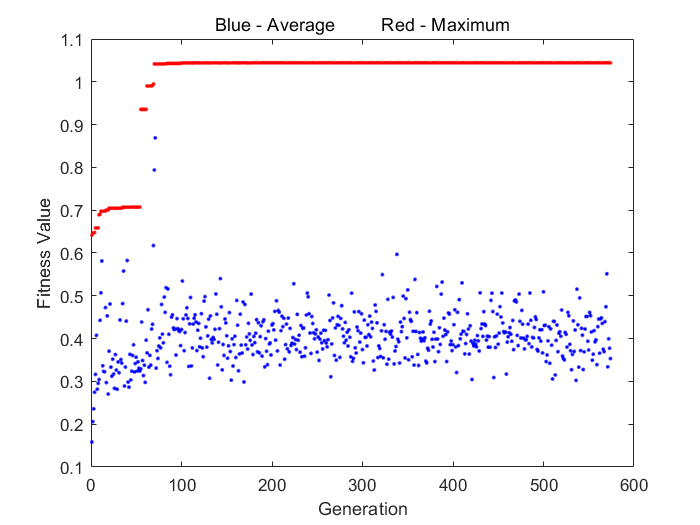

% Main Code
%--------------------------------------------------------------------------
% Note: if you use this code in your research and publication, please cite
% the orginal source: https://link.springer.com/article/10.1007/s13748-016-0091-3
% Thank you!
clear
clc
close all
tic
%--------------------------------------------------------------------------
% Population size
p =60;
% Number of pairs of chromosomes required for crossover
c=5;
% Number of chromosomes required for mutation
m=50;
% Adaptive stopping = no. of generations not improve quality
s=2;
% Number of chromosomes passing between generation
g=3;
% Number of chromosomes passing between runs
r=10;
%-------------------------------------------------------------------
% Computing time (s)
t = 10;
tg=1000000; % total number of generations (tg). We set tg very large to
% ensure that the GA will be stopped by computing time (t)
%--------------------------------------------------------------------------
P1=population(r); % Initial guess
w=1;
for j = 1:tg
    P=population(p-r);
    P(p-r+1:p,:)=P1;
    for i=1:tg   
        % Extended population
        P(p+1:p+2*c,:)=crossover(P,c);
        P(p+2*c+1:p+2*c+m,:)=mutation(P,m);
        %-----------------------------------------
        % Evaluation operation
        E=evaluation(P);
        [P S2]=selection(P,E,p,g);
        KK(w,1)=sum(S2)/p;
        KK(w,2)=S2(1,1);
        w=w+1;
        if w-1>s
            A=KK(w-s:w-1,2);
            B=abs(diff(A));
            if sum(B)<=0.0001
                break
            end
        end
        if toc > t
            break
        end
       
    end
    % Select top chromosomes
    for k = 1:r
        [x y]=find(S2==max(S2));
        P1(k,:)=P(max(y),:);
        P(max(y),:)=[];
        S2(:,max(y))=[];
        clear x y
    end
    % Note: P1 = top chromosomes
    if toc > t
        break
    end
    clear P
end
    figure
    plot(KK(:,1),'b.');
    hold all
    plot(KK(:,2),'r.');
    title('Blue - Average         Red - Maximum');
    xlabel('Generation')
    ylabel('Fitness Value')

    Max_fitness_value=max(KK(:,2))

Max_fitness_value = 1.0444

% convert to real number
    A=bi2de(P1(1,1:20));
    x=-40+A*(40-(-40))/(2^20-1);
    B=bi2de(P1(1,21:40));
    y=-40+B*(40-(-40))/(2^20-1);
    Optimal_solution=[x y]

Optimal_solution =    29.9997    0.0003
